clear; clc; close all

## Manual PID Tuning

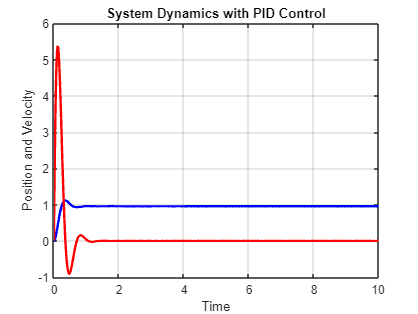

clear compute_pid_control

% Defining System Parameters
dynamics_params.mass = 1.0;                 % Mass of the object
dynamics_params.spring_constant = 5.0;      % Spring constant of the spring
dynamics_params.damping_coefficient = 0.1;  % Damping coefficient of the damper

% Initialize PID gains
gains = [100; 0.001; 10];

% Initial state [position; velocity]
initial_state = [0; 0];

% Desired state [desired_position; desired_velocity]
desired_state = [1; 0];

% Time span for simulation
tspan = [0, 10];  % Start time and end time


clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control');
grid on;


cost_manual = cost(gains,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_manual = 612.0727

## PID Gain Optimisation - ODE45

clear compute_pid_control

% interior point
options = optimoptions("fmincon","Display","iter",...
    "Algorithm","interior-point",...
    "EnableFeasibilityMode",true,...
    "SubproblemAlgorithm","cg");
gains_interiorP = fmincon(@(gains)cost(gains,desired_state,initial_state,dynamics_params,tspan,ones(2)),[100;0.01;10],[],[],[],[],[],[],@(gains)DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan),options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    1.323707e+03    1.519e-02    2.395e+08
    1       8    6.583301e+02    6.949e-03    2.778e+07    1.732e+00

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<

gains_interiorP =   101.7317
    0.0055
    9.9655


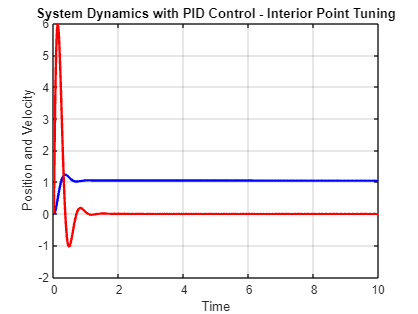



clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_interiorP, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Interior Point Tuning');
grid on;


cost_interiorP = cost(gains_interiorP,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_interiorP = 1.4607e+03

## PID Gain Optimisation - Genetic Algorithm

clear compute_pid_control

% Define the GA options
ga_options = optimoptions('ga', 'Display', 'iter', 'PopulationSize', 20, 'MaxGenerations', 25);

% Set the lower and upper bounds for the PID gains
lb = [10, 0.0005, 1]; % Lower bounds for Kp, Ki, and Kd
ub = [200, 0.06, 20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ga = ga(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, [], [], [], [], lb, ub, @(gains) DynamicConstODE(gains, desired_state, initial_state, dynamics_params, tspan), ga_options)


Single objective optimization:
3 Variable(s)
4 Nonlinear equality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1            540       164.061       0.3099      0
    2           1060       235.277     0.009584      0
    3           1580       577.877      0.09978      0
    4           2100        873.17      0.06228      0
    5           2620       1014.58      0.05099      0
    6           3140       346.478     0.003108      0
    7           3660       1099.98       0.0486      0
    8           4180       276.728     0.004928      0
    9           4700       1127.17      0.04673      0
   10           5220        476.01      0.02869      0
   11           5740       1173.59      0.04763      0
   12           6260    

gains_ga =    78.2568    0.0044    9.7559


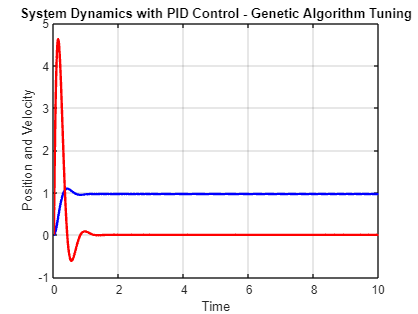



clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_ga, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Genetic Algorithm Tuning');
grid on;


cost_ga = cost(gains_ga,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_ga = 720.6366

## PID Gain Optimisation - Particle Swarm

clear compute_pid_control

% Define the GA options
ps_options = optimoptions('particleswarm', 'Display', 'iter', 'SwarmSize', 100);

% Set the lower and upper bounds for the PID gains
lb = [10, 0.0005, 1]; % Lower bounds for Kp, Ki, and Kd
ub = [200, 0.06, 20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ps = particleswarm(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, lb, ub, ps_options)


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100           412.9            1863        0
    1             200           160.2            1880        0
    2             300           160.2            1331        1
    3             400           159.5            1075        0
    4             500           159.5           989.1        1
    5             600           159.5           834.2        2
    6             700           159.5           608.7        3
    7             800           148.7           571.5        0
    8             900           148.7           538.9        1
    9            1000           148.7           376.6        2
   10            1100           148.7           655.6        3
   11            1200           148.7           392.5        4
   12            1300           148.7           464.8        5
   13            1400           148.7           

gains_ps =    10.0000    0.0005    5.8126


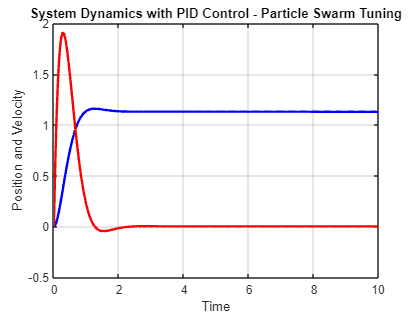



clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_ps, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Particle Swarm Tuning');
grid on;


cost_ps = cost(gains_ps,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_ps = 394.9282

## PID Gain Optimisation - with Pseudospectral Formulation

N = 21;

init = zeros(5, N+1);
init(3,1) = gains_ps(1);
init(4,1) = gains_ps(2);
init(5,1) = gains_ps(3);

options = optimoptions('fmincon','Display','iter','MaxFunctionEvaluations',1e11,'Algorithm','sqp',"EnableFeasibilityMode",true,'MaxIterations',5e3);

tf = 10; 
desired_state = [1; 0];
initial_state = [0; 0];
Q = ones(2);

[Z,~,flg] = fmincon(@(Z)cost_pseudospectral(Z,desired_state,Q,N,tf),init,[],[],[],[],[],[],@(Z)NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf),options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         111    9.988662e+00     1.001e+01     1.000e+00     0.000e+00     1.492e+00  
    1         222    4.365843e-01     5.012e+00     1.000e+00     6.263e+00     1.496e+03  
    2         333    7.548825e-01     2.613e-01     1.000e+00     1.345e+00     1.228e+03  
    3         444    7.838112e-01     2.523e-01     1.000e+00     6.342e-01     1.295e+03  
    4         560    7.788668e-01     2.484e-01     1.681e-01     3.106e-01     1.289e+03  
    5         683    7.747142e-01     2.469e-01     1.384e-02     1.102e-01     1.278e+03  
    6         808    7.713355e-01     2.459e-01     6.782e-03     7.805e-02     1.270e+03  
    7         935    7.686027e-01     2.453e-01     3.323e-03     5.638e-02     1.261e+03  
    8        1062    7.650067e-01     2.445e-01     3.323e-03     7.135e-02     1.

gains_psuedospectral = Z(3:5,1).'

gains_psuedospectral =    38.8622    0.0600   11.6550


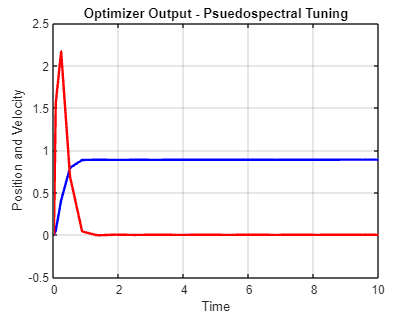


[nodes,~] = clencurt(N);
tspan_ = ((flip(nodes)+1)/2).*tf;
%%

wk = zeros(N+1);
wk(1) = 0;

for i = 1:N
    [~,weights] = clencurt(i);
    wk(i+1,1:i+1) = weights';
    wk(i+1,:) = wk(i+1,:)*tspan_(i+1);
end

% Extract position and velocity for plotting
position = Z(1, :);
velocity = Z(2, :);

% Plot the results
figure;
plot(tspan_, position, 'b', 'LineWidth', 2);
hold on;
plot(tspan_, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('Optimizer Output - Psuedospectral Tuning');
grid on;

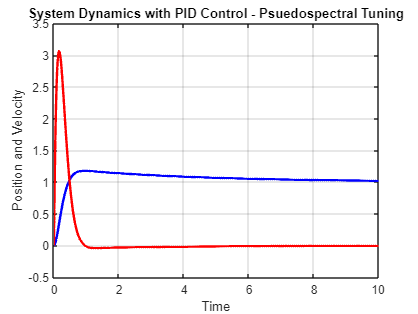

clear compute_pid_control

% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_psuedospectral, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Psuedospectral Tuning');
grid on;


cost_pseudospec = cost(gains_psuedospectral,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_pseudospec = 1.3728e+03

## Non-Linear Constraint for Pseudospectral Optimisation

function [c,ceq] = NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf)
    
    state = Z(1:2,:);
    gains = Z(3:5,1);

    Kp = gains(1);
    Ki = gains(2);
    Kd = gains(3);

    c(1) = Kp - 200;
    c(2) = Ki - 0.06;
    c(3) = Kd - 20;
    c(4) = 10 - Kp;
    c(5) = 0.0005 - Ki;
    c(6) = 1 - Kd;

    % Use Guass-Quadrature integration to simulate system dynamics with PID
    error = desired_state(1,:) - state(1,:);
    integral = zeros(size(error));
    integral(:,1) = error(:,1);

    velocity_error = desired_state(2,:) - state(2,:);

    % [~,wk] = clencurt(N);
    wk = zeros(N+1);
    wk(1) = 0;
    
    [nodes,~] = clencurt(N);
    tspan_ = ((flip(nodes)+1)/2).*tf;
    for i = 1:N
        [~,weights] = clencurt(i);
        wk(i+1,1:i+1) = weights';
        wk(i+1,:) = wk(i+1,:)*tspan_(i+1);
    end

    % for i = 2:size(state,2)
    %     integral(:,i) = integral(:,i-1) + wk(i)*error(:,i);
    % end

    for i = 1:1 % Detemines which variables error
        for j = 2:size(state,2) % Determines which node it is being calculated at
            integral(i,j) = sum(wk(j,:)*error(:,j));
        end
    end

    D = -DCPeyret(N+1);

    % Unpack state variables
    position = state(1,:);
    velocity = state(2,:);

    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    input = Kp*error + Ki*integral + Kd*velocity_error;

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    c_dynamics = ((2/tf)*D*state.').' - ([velocity; acceleration]);
    reshape(c_dynamics, [], 1);

    ceq_init = state(:,1) - initial_state;
    ceq_des = state(:,end) - desired_state;

    ceq = vertcat(reshape(ceq_init,[2,1]),reshape(ceq_des,[2,1]),reshape(c_dynamics, [], 1));
end

%% Cost Pseudospectral Optimisation
function J = cost_pseudospectral(Z,desired_state,Q,N,tf)

    [~,wk] = clencurt(N);
    
    state = Z(1:2,:);
    J = 0;
    for i = 1:N
        J = J + wk(i)*((state(:,i)-desired_state).'*Q*(state(:,i)-desired_state));
    end
    J = J.*(tf/2);
end 

## System Dynamics Constraint Function - ODE

function [c,ceq] = DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan)
    c = [];

    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains, y, desired_state), dynamics_params), tspan, initial_state);
   
    ceq_init = y(1,:) - initial_state.';
    ceq_des = y(end,:) - desired_state.';

    ceq = vertcat(reshape(ceq_init,[2,1]),reshape(ceq_des,[2,1]));
end 

## Cost Function

function J = cost(gains,desired_state,initial_state,dynamics_params,tspan,R)
    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains, y, desired_state), dynamics_params), tspan, initial_state);
    
    J = 0;
    for timestep = 1:size(y,1)
        state = y(timestep,:);
        J = J + state*R*state.';
    end 
end 

## Input Calculator - PID - persistent variables

function control_input = compute_pid_control(gains, state, desired_state)
    % gains: PID gain vector [Kp; Ki; Kd]
    % state: State vector [position; velocity]
    % desired_state: Desired state vector [position; velocity]

    % PID error computation
    position_error = desired_state(1) - state(1);
    velocity_error = desired_state(2) - state(2);

    % Initialize persistent integral error variable (only done on the first function call)
    persistent integral_error
    if isempty(integral_error)
        integral_error = 0;
    end

    % Compute the integral term using trapezoidal rule and update the persistent variable
    integral_error = integral_error + position_error;

    % PID control law
    P_term = gains(1) * position_error;
    I_term = gains(2) * integral_error;
    D_term = gains(3) * velocity_error;

    % Compute the PID control input
    control_input = P_term + I_term + D_term;
end

## Spring Mass Damper System Dynamics

function dydt = dynamics(t, state, input, dynamics_params)
    % t: Time (not used in this function, but required for numerical integration)
    % state: State vector [position; velocity]
    % input: Control input applied to the system (force)
    % dynamics_params: struct containing system dynamic parameters (mass,
    % spring_constant, damping_coefficient)

    % Unpack state variables
    position = state(1);
    velocity = state(2);

    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    % Return the derivative of the state variables
    dydt = [velocity; acceleration];
end



## Chebyshev Pseudospectral Method

function [x,w] = clencurt(N)
    % File to compute CGL Nodes x and
    % Clenshaw-Curtis Quadrature Weights w

    theta = pi*(0:N)'/N;
    x = cos(theta);

    w = zeros(N+1,1);
    i = 2:N;
    v = ones(N-1,1);

    if mod(N,2) == 0
        w(1) = 1/(N^2 -1);
        w(N+1) = w(1);

        for j = 1:0.5*N-1
           v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
        v = v - cos(N*theta(i))/(N^2 - 1);
    else
        % CHECK ODD CASE
        w(1) = 1/N^2;
        w(N+1) = w(1);

        for j = 1:0.5*(N-1)
            v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
    end
    w(i) = 2*v/N;
end

function D = DCPeyret(N)
    % Peyret's D matrix
    D = zeros(N);
    D(1,1) = (2*(N-1)^2 + 1)/6;
    D(N,N) = -(2*(N-1)^2 + 1)/6;
    m = 0:N-1;
    ndsP = cos(m*pi/(N-1));
    cbar = ones(N,1);
    cbar(1) = 2;
    cbar(N) = 2;
    
    for i = 1:N
        if i ~= 1 && i ~= N
            D(i,i) = -0.5*ndsP(i)/(1- ndsP(i)^2);
        end
        
        for j = setdiff(1:N,i)
            D(i,j) = cbar(i) * (-1)^(i + j) / (cbar(j) * (ndsP(i) - ndsP(j)));
        end
    end
end 
